images = imageDatastore("data\", "IncludeSubfolders", true, "LabelSource", "foldernames");
countEachLabel(images)

figure;
It = imread("people_1.jpg");
imshow(It);
hold on
[hogt,vist] = extractHOGFeatures(It);
plot(vist)

% Przygotowanie danych treningowych
X_train = zeros(length(images.Files), 3780);
Y_train = images.Labels;

for i=1:length(images.Files)
    if mod(i, 500) == 0
        fprintf("Extracting HOG features i=%d...\n", i);
    end
    I = imread(images.Files{i});
    try
        [hog, vis] = extractHOGFeatures(I);
        X_train(i,:) = hog;
    catch ME
        fprintf("Error processing file %s", images.Files{i});
        fprintf("Error: %s", ME);
    end
end


% Wytrenowanie klasyfikatora SVM
C = 10;
gamma = 0.1;

img_classes = {'pos', 'neg_64'};

t = templateSVM('KernelFunction','gaussian','BoxConstraint', C, 'KernelScale',gamma);
model   = fitcecoc(X_train, Y_train, 'Learners', t, 'ClassNames', img_classes);


scale = 1

count_x = 25

count_y = 11

level=1 count_x=25 count_y=11

level=1 0/275 (j=0, i=0)... 
level=1 1/275 (j=0, i=1)... 
level=1 2/275 (j=0, i=2)... 
level=1 3/275 (j=0, i=3)... 
level=1 4/275 (j=0, i=4)... 
level=1 5/275 (j=0, i=5)... 
level=1 6/275 (j=0, i=6)... 
level=1 7/275 (j=0, i=7)... 
level=1 8/275 (j=0, i=8)... 
level=1 9/275 (j=0, i=9)... 
level=1 10/275 (j=0, i=10)... 
level=1 11/275 (j=0, i=11)... 
level=1 12/275 (j=0, i=12)... 
level=1 13/275 (j=0, i=13)... 
level=1 14/275 (j=0, i=14)... 
level=1 15/275 (j=0, i=15)... 
level=1 16/275 (j=0, i=16)... 
level=1 17/275 (j=0, i=17)... 
level=1 18/275 (j=0, i=18)... 
level=1 19/275 (j=0, i=19)... 
level=1 20/275 (j=0, i=20)... 
level=1 21/275 (j=0, i=21)... 
level=1 22/275 (j=0, i=22)... 
level=1 23/275 (j=0, i=23)... 
level=1 24/275 (j=0, i=24)... 
level=1 25/275 (j=1, i=0)... 
level=1 26/275 (j=1, i=1)... 
level=1 27/275 (j=1, i=2)... 
level=1 28/275 (j=1, i=3)... 
level=1 29/275 (j=1, i=4)... 
level=1 30/275 (j=1, i=5)... 
level=1 31/275 (j=1, i=6)... 
level=1 32/275 (j=1, i=7)... 
level

best_score = 1

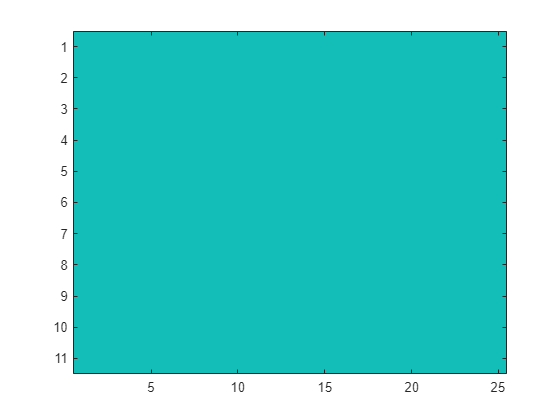

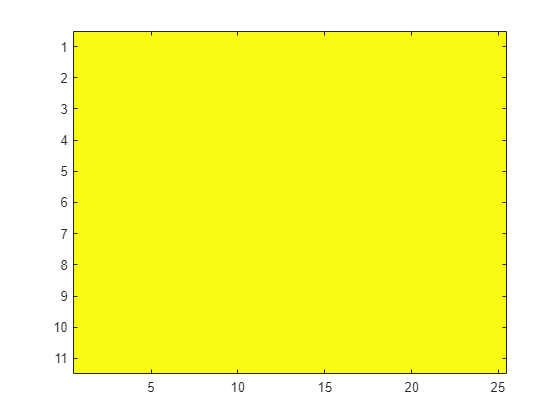

scale = 0.8000

count_x = 20

count_y = 8

level=2 count_x=20 count_y=8

level=2 0/160 (j=0, i=0)... 
level=2 1/160 (j=0, i=1)... 
level=2 2/160 (j=0, i=2)... 
level=2 3/160 (j=0, i=3)... 
level=2 4/160 (j=0, i=4)... 
level=2 5/160 (j=0, i=5)... 
level=2 6/160 (j=0, i=6)... 
level=2 7/160 (j=0, i=7)... 
level=2 8/160 (j=0, i=8)... 
level=2 9/160 (j=0, i=9)... 
level=2 10/160 (j=0, i=10)... 
level=2 11/160 (j=0, i=11)... 
level=2 12/160 (j=0, i=12)... 
level=2 13/160 (j=0, i=13)... 
level=2 14/160 (j=0, i=14)... 
level=2 15/160 (j=0, i=15)... 
level=2 16/160 (j=0, i=16)... 
level=2 17/160 (j=0, i=17)... 
level=2 18/160 (j=0, i=18)... 
level=2 19/160 (j=0, i=19)... 
level=2 20/160 (j=1, i=0)... 
level=2 21/160 (j=1, i=1)... 
level=2 22/160 (j=1, i=2)... 
level=2 23/160 (j=1, i=3)... 
level=2 24/160 (j=1, i=4)... 
level=2 25/160 (j=1, i=5)... 
level=2 26/160 (j=1, i=6)... 
level=2 27/160 (j=1, i=7)... 
level=2 28/160 (j=1, i=8)... 
level=2 29/160 (j=1, i=9)... 
level=2 30/160 (j=1, i=10)... 
level=2 31/160 (j=1, i=11)... 
level=2 32/160 (j=1, i=12)... 
level=2

best_score = 1

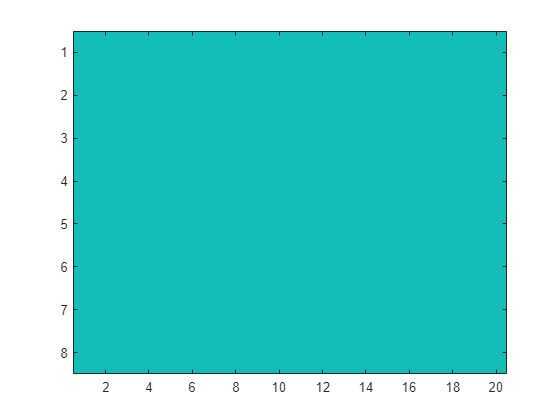

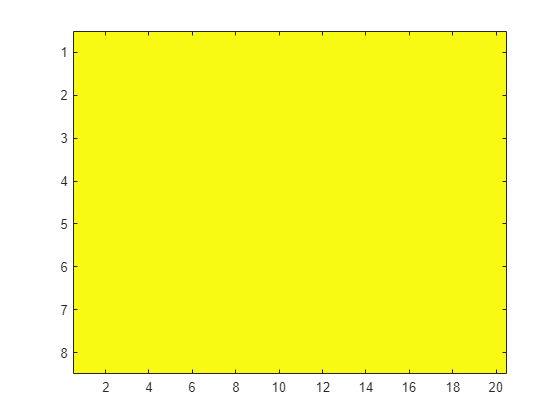

scale = 0.6400

count_x = 15

count_y = 5

level=3 count_x=15 count_y=5

level=3 0/75 (j=0, i=0)... 
level=3 1/75 (j=0, i=1)... 
level=3 2/75 (j=0, i=2)... 
level=3 3/75 (j=0, i=3)... 
level=3 4/75 (j=0, i=4)... 
level=3 5/75 (j=0, i=5)... 
level=3 6/75 (j=0, i=6)... 
level=3 7/75 (j=0, i=7)... 
level=3 8/75 (j=0, i=8)... 
level=3 9/75 (j=0, i=9)... 
level=3 10/75 (j=0, i=10)... 
level=3 11/75 (j=0, i=11)... 
level=3 12/75 (j=0, i=12)... 
level=3 13/75 (j=0, i=13)... 
level=3 14/75 (j=0, i=14)... 
level=3 15/75 (j=1, i=0)... 
level=3 16/75 (j=1, i=1)... 
level=3 17/75 (j=1, i=2)... 
level=3 18/75 (j=1, i=3)... 
level=3 19/75 (j=1, i=4)... 
level=3 20/75 (j=1, i=5)... 
level=3 21/75 (j=1, i=6)... 
level=3 22/75 (j=1, i=7)... 
level=3 23/75 (j=1, i=8)... 
level=3 24/75 (j=1, i=9)... 
level=3 25/75 (j=1, i=10)... 
level=3 26/75 (j=1, i=11)... 
level=3 27/75 (j=1, i=12)... 
level=3 28/75 (j=1, i=13)... 
level=3 29/75 (j=1, i=14)... 
level=3 30/75 (j=2, i=0)... 
level=3 31/75 (j=2, i=1)... 
level=3 32/75 (j=2, i=2)... 
level=3 33/75 (j=2, i=3)... 
level=3 34/75 

best_score = 1

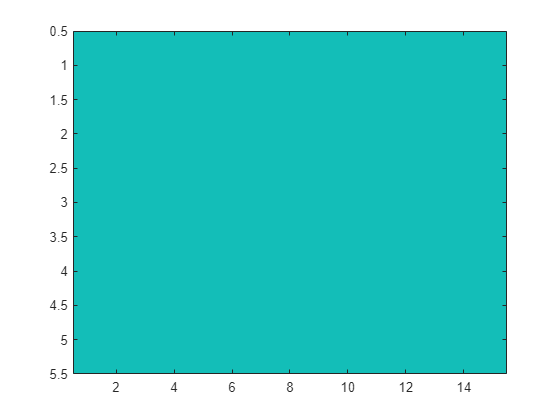

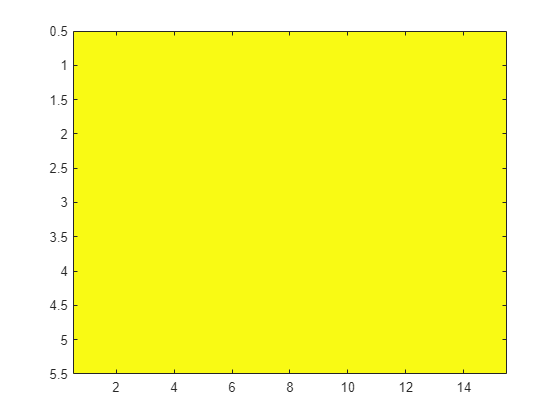

scale = 0.5120

count_x = 11

count_y = 3

level=4 count_x=11 count_y=3

level=4 0/33 (j=0, i=0)... 
level=4 1/33 (j=0, i=1)... 
level=4 2/33 (j=0, i=2)... 
level=4 3/33 (j=0, i=3)... 
level=4 4/33 (j=0, i=4)... 
level=4 5/33 (j=0, i=5)... 
level=4 6/33 (j=0, i=6)... 
level=4 7/33 (j=0, i=7)... 
level=4 8/33 (j=0, i=8)... 
level=4 9/33 (j=0, i=9)... 
level=4 10/33 (j=0, i=10)... 
level=4 11/33 (j=1, i=0)... 
level=4 12/33 (j=1, i=1)... 
level=4 13/33 (j=1, i=2)... 
level=4 14/33 (j=1, i=3)... 
level=4 15/33 (j=1, i=4)... 
level=4 16/33 (j=1, i=5)... 
level=4 17/33 (j=1, i=6)... 
level=4 18/33 (j=1, i=7)... 
level=4 19/33 (j=1, i=8)... 
level=4 20/33 (j=1, i=9)... 
level=4 21/33 (j=1, i=10)... 
level=4 22/33 (j=2, i=0)... 
level=4 23/33 (j=2, i=1)... 
level=4 24/33 (j=2, i=2)... 
level=4 25/33 (j=2, i=3)... 
level=4 26/33 (j=2, i=4)... 
level=4 27/33 (j=2, i=5)... 
level=4 28/33 (j=2, i=6)... 
level=4 29/33 (j=2, i=7)... 
level=4 30/33 (j=2, i=8)... 
level=4 31/33 (j=2, i=9)... 
level=4 32/33 (j=2, i=10)... 


best_score = 1

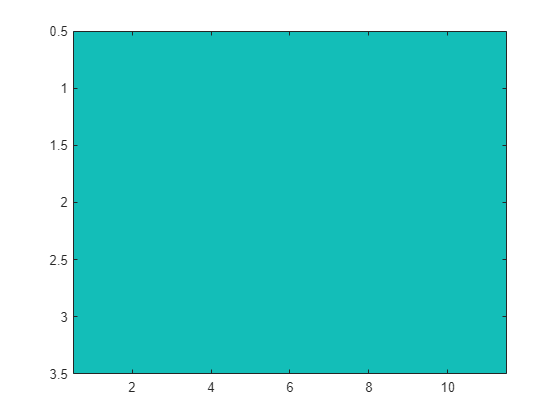

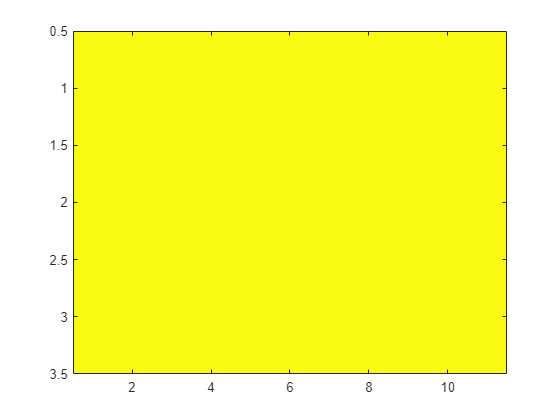

scale = 0.4096

count_x = 9

count_y = 1

level=5 count_x=9 count_y=1

level=5 0/9 (j=0, i=0)... 
level=5 1/9 (j=0, i=1)... 
level=5 2/9 (j=0, i=2)... 
level=5 3/9 (j=0, i=3)... 
level=5 4/9 (j=0, i=4)... 
level=5 5/9 (j=0, i=5)... 
level=5 6/9 (j=0, i=6)... 
level=5 7/9 (j=0, i=7)... 
level=5 8/9 (j=0, i=8)... 


best_score = 1

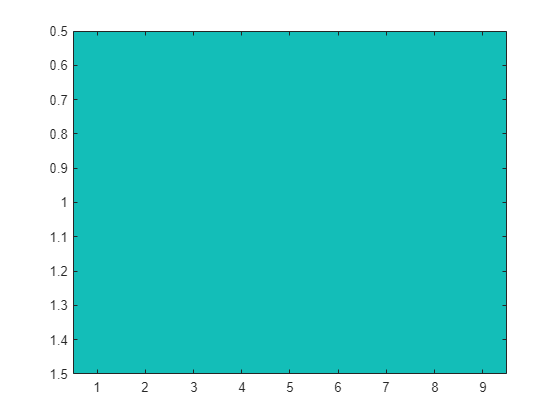

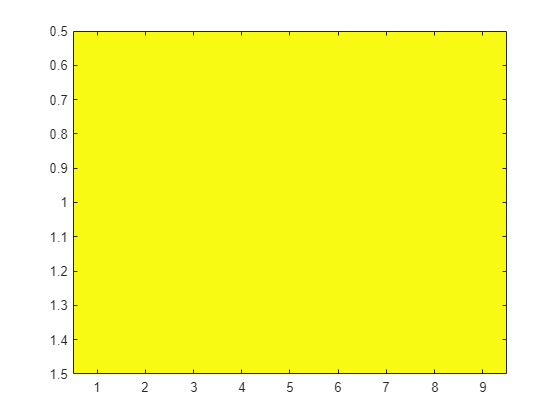


% Weryfikacja klasyfikatora
sx = 64;
sy = 128;
step = 24;

scale_step = 0.8;
levels = 5;

scale = 1.0;
thr = 60;

dets = [];
scores = [];
labels = {};


for k=1:levels

scale
cur_img = imresize(It, scale);

w = size(cur_img, 2);
h = size(cur_img, 1);

count_x = floor((w - sx) / step)
count_y = floor((h - sy) / step)

fprintf("level=%d count_x=%d count_y=%d", k, count_x, count_y)

out = zeros(count_y, count_x);

for j=0:count_y-1
    for i=0:count_x-1
        fprintf("level=%d %d/%d (j=%d, i=%d)... \n", k, j*count_x+i, count_y*count_x, j, i);
        x = 1+(i*step);
        y = 1+(j*step);
        sub_img = cur_img(y:y+sy, x:x+sx);
        sub_hog = extractHOGFeatures(sub_img);
        pred = model.predict(sub_hog);
        out(j+1, i+1) = strcmp(pred, 'pos');
    end
end

best_score = min(min(out))

figure;
imagesc(out)
figure;
mins = imregionalmin(out);
mins(out > thr) = 0;
imagesc(mins);
[rs, cs] = find(mins);

for i=1:size(rs)
    x = ((cs(i)-1) * step) / scale + 1;
    y = ((rs(i)-1) * step) / scale + 1;
    w = sx / scale;
    h = sy / scale;

    dets = [dets; [x,y,w,h] ];
    scores = [scores, out(rs(i), cs(i))];
    labels{size(dets, 1)} = num2str(out(rs(i), cs(i)), '%.1f');
end

scale = scale * scale_step;

end

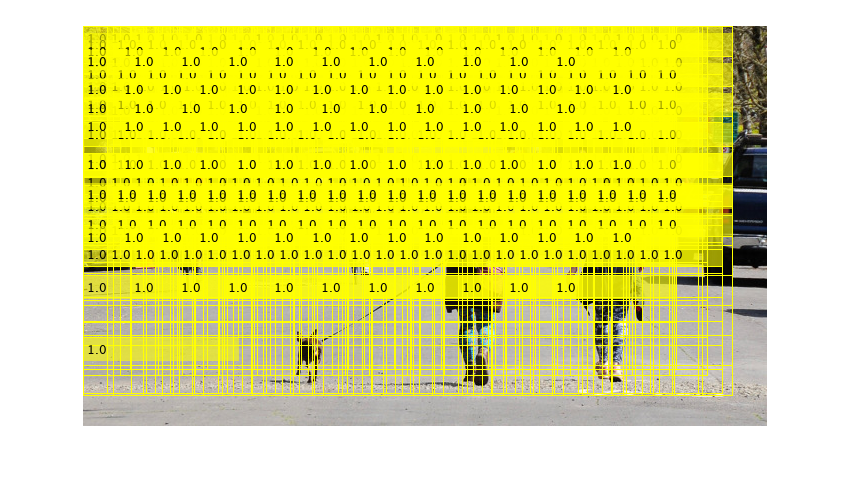

imshow(insertObjectAnnotation(It, 'rectangle', dets, labels));

### Filtracja detekcji i NMS

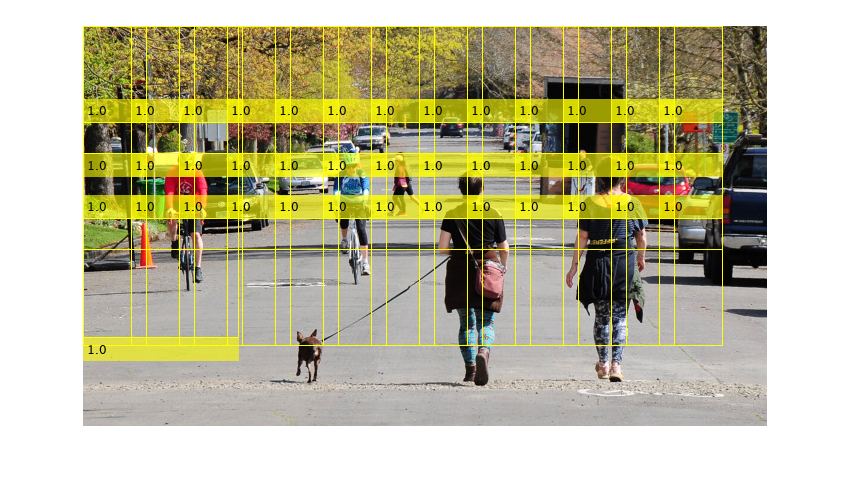

filtered_dets = [];
filtered_scores = [];
tmp_dets = dets;
tmp_scores = scores;
while 1
    [m, i] = min(tmp_scores);
    filtered_dets = [filtered_dets; tmp_dets(i,:)];
    filtered_scores = [filtered_scores, m];
    ratio = bboxOverlapRatio(tmp_dets(i, :), tmp_dets);
    tmp_dets = tmp_dets(ratio < 0.2, :);
    tmp_scores = tmp_scores(ratio < 0.2);
    if size(tmp_dets, 1) < 1
        break
    end
end
cnt = size(filtered_scores, 2);
filtered_lbls = cell(cnt, 1);
for i=1:cnt
    filtered_lbls{i} = num2str(filtered_scores(i), '%.1f');
end
imshow(insertObjectAnnotation(It, "rectangle", filtered_dets, filtered_lbls));

gt_rect=gTruth.LabelData.person{1,1};

Unable to resolve the name 'gTruth.LabelData.person'.

ann1 = insertObjectAnnotation(It, "rectangle", gt_rect, "person");
imshow(ann1);
score_thr = 30;
selected_dets = filtered_dets(filtered_scores < score_thr, :);
ratio = bboxOverlapRatio(gt_rect, selected_dets)
[best_overlaps, good_ids] = max(ratio, [], 2)
iou = 0.4;
best_ids = good_ids(best_overlaps > iou)
pos_neg = zeros(size(selected_dets, 1), 1);
pos_neg(best_ids) = 1;
tp_boxes = selected_dets(pos_neg==1, :);
fp_boxes = selected_dets(pos_neg==0, :);
ann2 = insertObjectAnnotation(ann1, "rectangle", fp_boxes, "", "Color", 'red');
ann2 = insertObjectAnnotation(ann2, "rectangle", tp_boxes, "", "Color", 'green');
imshow(ann2)

[P, R, sc] = calcpr(filtered_dets, filtered_scores, gt_rect, 0.4);
figure;
plot(sc, P);
hold on
plot(sc, R);
legend(["Precision", "Recall"]);
xlabel("Score");
ylabel("%");
figure;
plot(R, P, 'x-');
xlabel("Recall");
ylabel("Precision");
ap = trapz(R, P)

function [P, R, sc] = calcpr(dets, scores, gt_rect, iou)
    cnt = size(scores, 2) + 1;
    P = zeros(cnt, 1);
    R = zeros(cnt, 1);
    sorted_scores = sort(scores);
    
    sorted_scores = [0, sorted_scores];
    sc = sorted_scores;
    
    all_pos = size(gt_rect, 1);
    
    P(1) = 1;
    R(1) = 0;
    
    for ii=2:cnt
        score_thr = sorted_scores(ii);
        selected_dets = dets(scores <= score_thr, :);
        ratio = bboxOverlapRatio(gt_rect, selected_dets);
        [best_overlaps, good_ids] = max(ratio, [], 2);
        best_ids = good_ids(best_overlaps > iou);
        tp = size(best_ids, 1);
        fn = all_pos - tp;
        fp = size(selected_dets, 1) - tp;
        P(ii) = tp / (tp + fp);
        R(ii) = tp / (tp + fn);
    end
end